Load the data


rng('default') %For reproductivity
T=readtable('datset Individual Assignment.xlsx')

T = 3202×19 table
     datetime       T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     OBSERVED     U_mu 
    ___________    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    ______    

## **TASK 1**

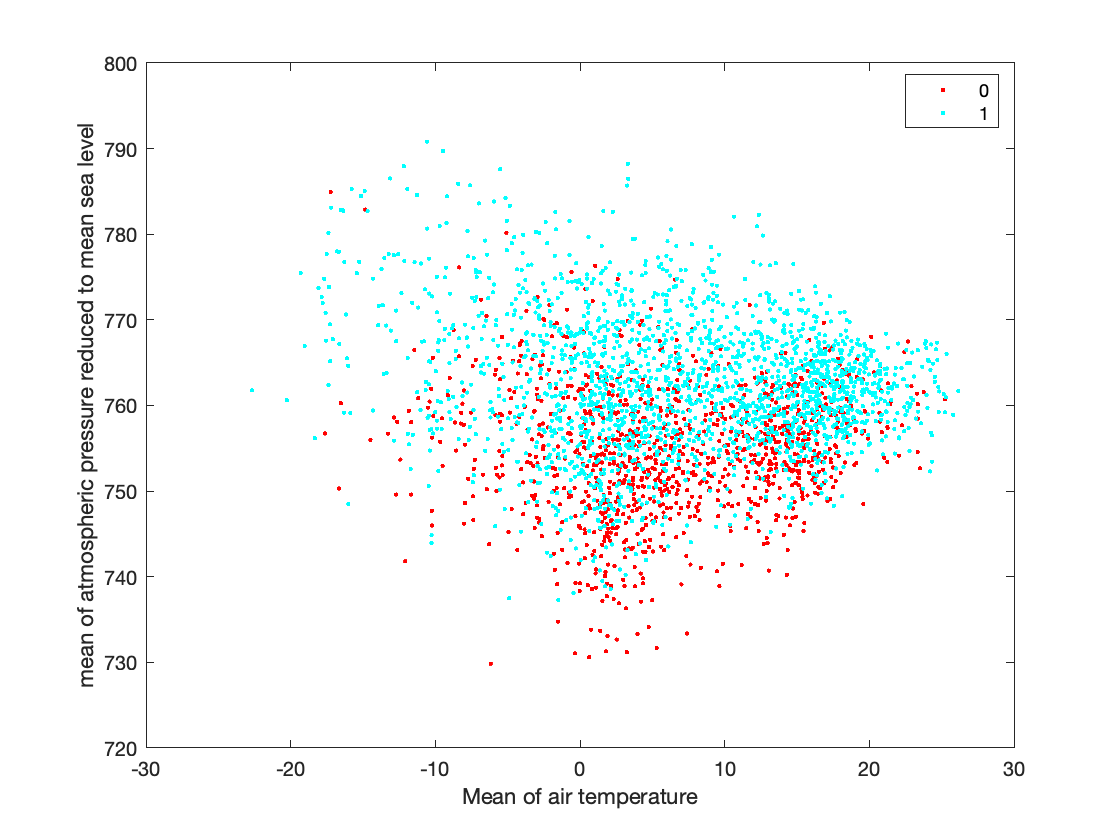


% (1) 2D Scatter plot
gscatter(T.T_mu,T.P_mu,T.OBSERVED)
xlabel('Mean of air temperature')
ylabel('mean of atmospheric pressure reduced to mean sea level')

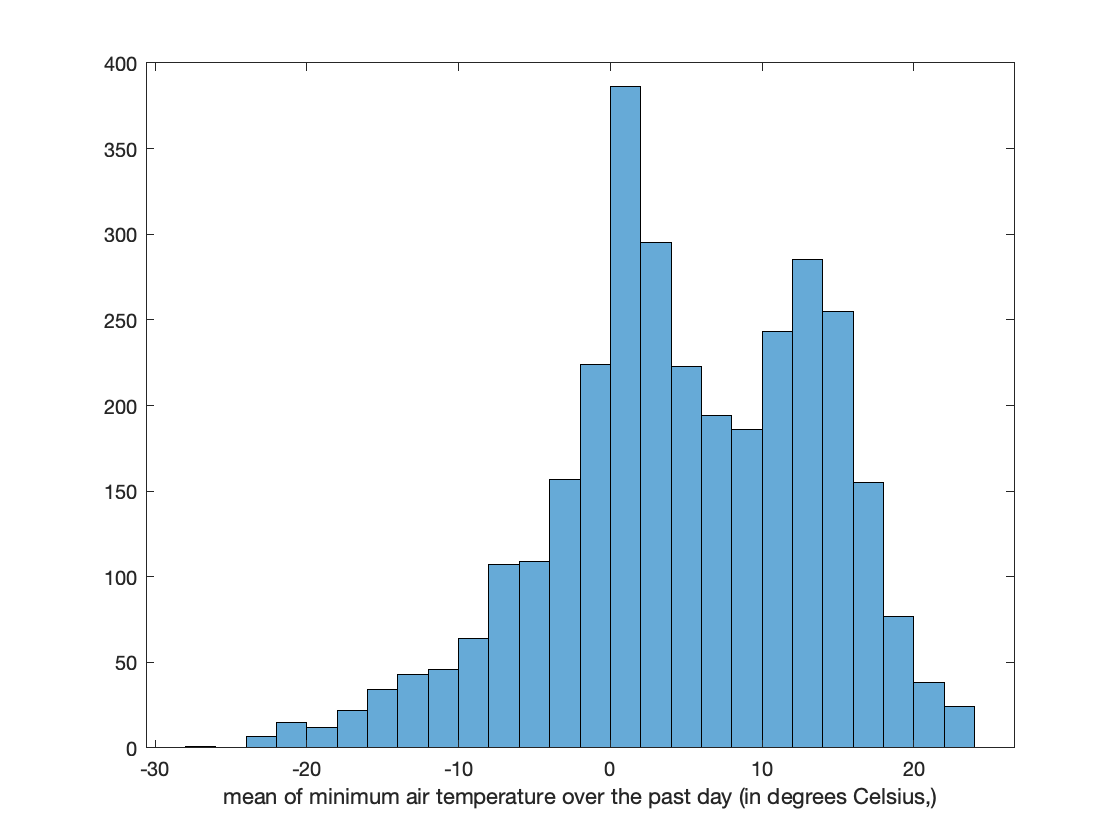


%(2) histogram of the variable Tn_mu
histogram(T.Tn_mu)
xlabel('mean of minimum air temperature over the past day (in degrees Celsius,)')



%(3) Two groups of variable Td_mu
[moisture,moistureV,] = findgroups(T.OBSERVED)

moisture =      2
     2
     1
     1
     1
     1
     1
     2
     2
     2


moistureV =      0
     1


maxvalueTd_mu=splitapply(@max,T.Td_mu,moisture)

maxvalueTd_mu =    20.3000
   21.4625


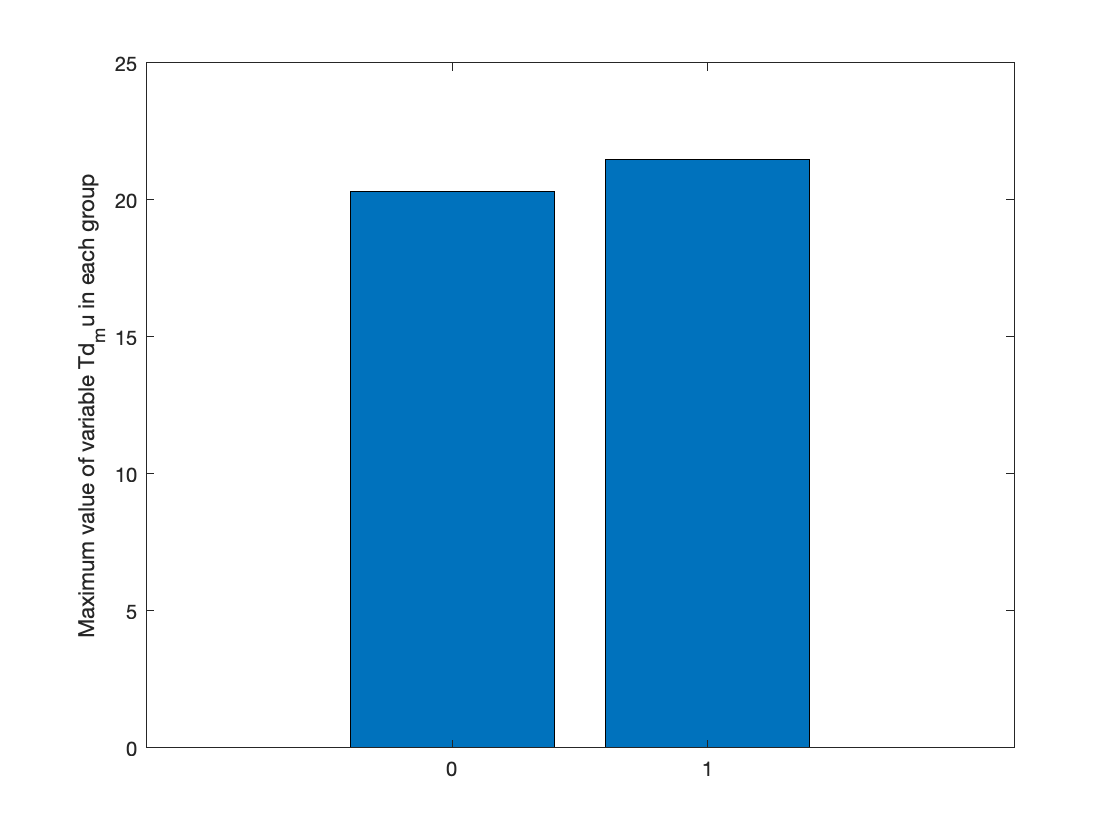

bar(maxvalueTd_mu)
xticklabels(moistureV)
ylabel("Maximum value of variable Td_mu in each group")



%(4) mean value of P_var 
meanvalueP_var=splitapply(@max,T.P_var,moisture)

meanvalueP_var =    89.8079
   84.3784


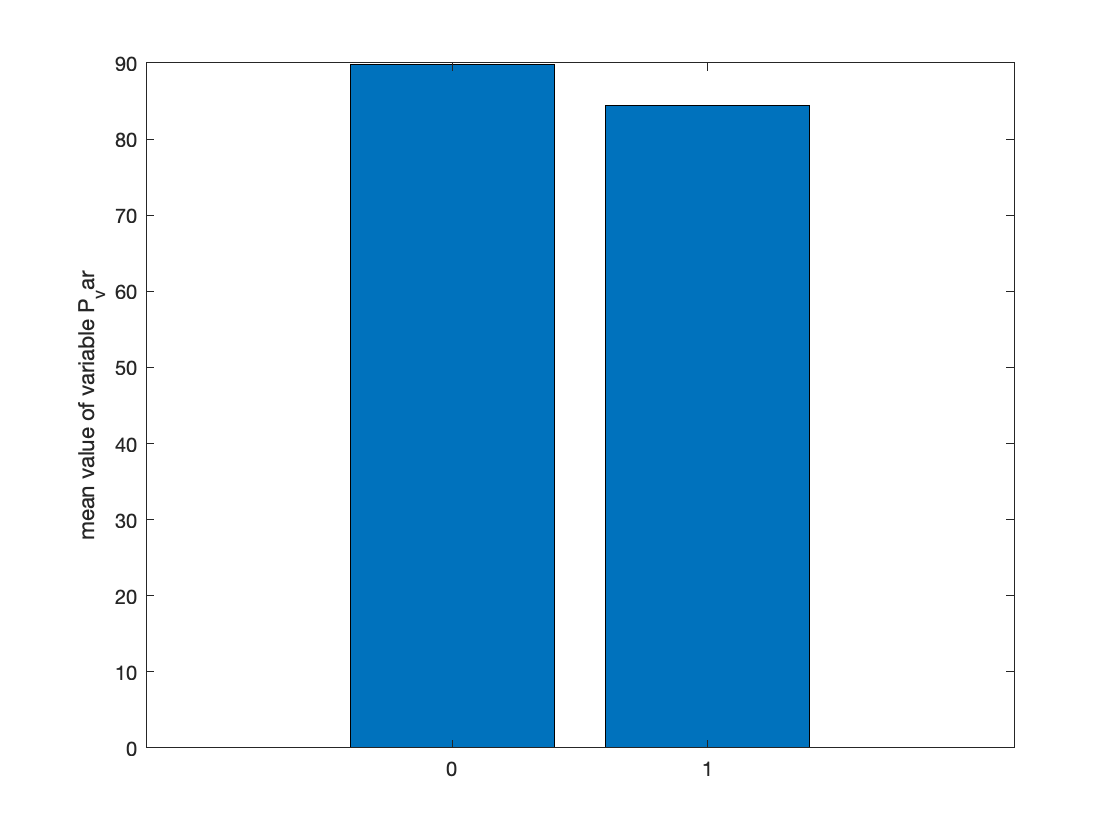

bar(meanvalueP_var)
xticklabels(moistureV)
ylabel("mean value of variable P_var")


%(5) splitting date into 3 coloumn
[T.YYYY,T.MM,T.DD] = ymd(T.datetime);
T.datetime=[];

%(6) Storing the predator matrix in variable X and target variables in Y1
%which is categorical and In Y2 which is countinous
X=T(:,[1:16 19:21])

X = 3202×19 table
     T_mu      Po_mu      P_mu     Ff_mu     Tn_mu     Tx_mu      W_mu      Td_mu      T_var     Po_var      P_var     Ff_var     Tn_var    Tx_var    W_var     Td_var     YYYY    MM    DD
    _______    ______    ______    ______    ______    ______    ______    _______    _______    _______    _______    _______    ______    ______    ______    _______    ____    

Y1=T(:,17)

Y1 = 3202×1 table
    OBSERVED
    ________

       1    
       1    
       0    
       0    
       0    
       0    
       0    
       1    
       1    
       1    
       1    
       1    
       0    
       1    
       1    
       1    


Y2=T(:,18)

Y2 = 3202×1 table
     U_mu 
    ______

     86.25
    82.875
     88.75
    91.833
        89
    89.875
    92.125
    85.625
    88.875
     92.75
     94.75
      99.5
    99.857
    99.625
      97.5
     87.25


## **TASK 2**


%(1)Adopting PCA to reduce the dimension of predictor matrix X
X=table2array(X)

X = 	1.0e+03 *

   -0.0129    0.7555    0.7559    0.0043   -0.0140   -0.0105    0.0194   -0.0147    0.0062    0.0093    0.0093    0.0011    0.0034    0.0003    0.1673    0.0078    2.0100    0.0010    0.0010
   -0.0174    0.7620    0.7624    0.0036   -0.0186   -0.0152    0.0279   -0.0196    0.0015    0.0011    0.0011    0.0006    0.0008    0.0000    0.0233    0.0011    2.0100    0.0010    0.0020
   -0.0126    0.7577    0.7581    0.0025   -0.0218   -0.0104    0.0193   -0.0141    0.0666    0.0171    0.0173    0.0017         0    0.1051    0.2369    0.0774    2.0100    0.0010    0.0030
   -0.0039    0.7506    0.7510    0.0034   -0.0077   -0.0024    0.0291   -0.0055    0.0035    0.0013    0.0013    0.0006    0.0004    0.0003    0.2723    0.0008    2.0100    0.0010    0.0040
   -0.0095    0.7526    0.7530    0.0037   -0.0113   -0.0042    0.0341   -0.0110    0.0215    0.0119    0.0119    0.0014    0.0224    0.0211    0.0633    0.0307    2.0100    0.0010    0.0050
   -0.0112    0.7605    0.760

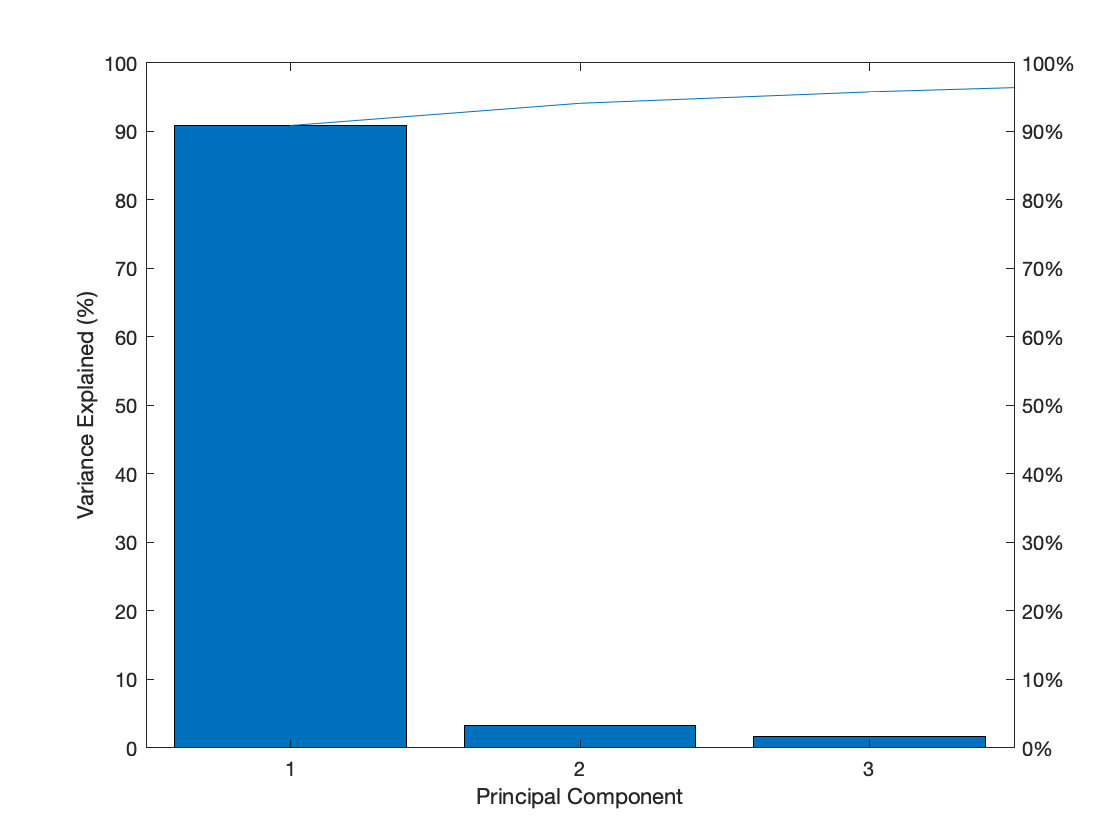

[coeff,score,latent,~,explained]= pca(X);

% Ploting the cumulative explained variance
figure()
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')






% for reproductivity
rng('default') 
%(2) using the principle component which explained 94% of variance and
%stored in variable NewX and making clusters
NewX=score(:,1:2)

NewX =    89.9359  -37.8463
  -54.1187  -46.2131
  159.7424  -41.7797
  194.8846  -17.8025
  -13.7091  -27.0421
   45.3924  -34.8000
  -33.7830  -32.5822
  -57.3343  -46.6305
  -63.3178  -45.8077
  -62.1080  -43.0440


% 2 cluster
[cidx2,cmeans2] = kmeans(NewX,2);
%3 cluster
[cidx3,cmeans3] = kmeans(NewX,3);
%4 cluster
[cidx4,cmeans4] = kmeans(NewX,4);
%5 cluster
[cidx5,cmeans5] = kmeans(NewX,5);

%The following function call creates 2, 3, 4, 5 clusters using k-means clustering, and calculates the
%silhouette value for each clustering scheme. When using'kmeans' , evalclusters by default uses the
%squared Euclidian distance
E = evalclusters(NewX,'kmeans','silhouette','klist',[2:5])

E =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4 5]
    CriterionValues: [0.8583 0.7905 0.7145 0.6600]
           OptimalK: 2



% The output variable, E , contains detailed information about the evaluation including the optimum number of
kbest = E.OptimalK

kbest = 2

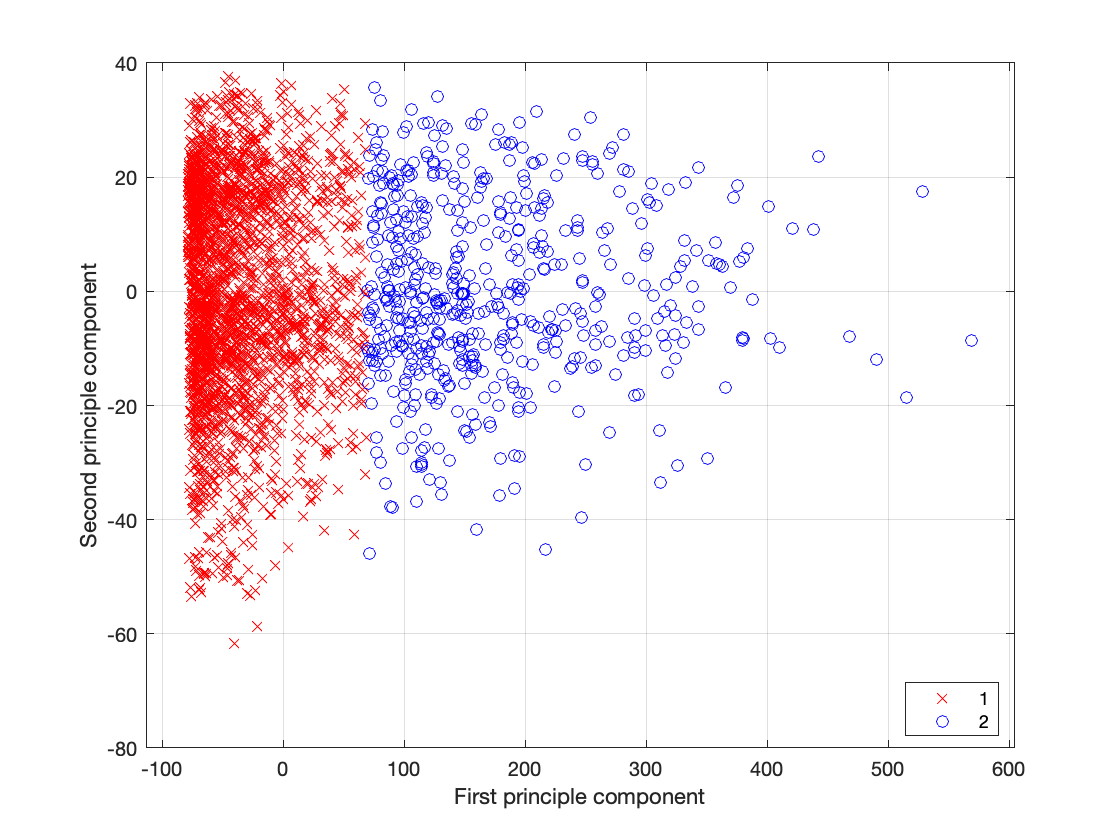

% cluster 2 have the highest silhoute value so we will choose cluster 2 
figure;
gscatter(NewX(:,1),NewX(:,2),E.OptimalY,'rbg','xod')
xlabel('First principle component');
ylabel('Second principle component');
grid on

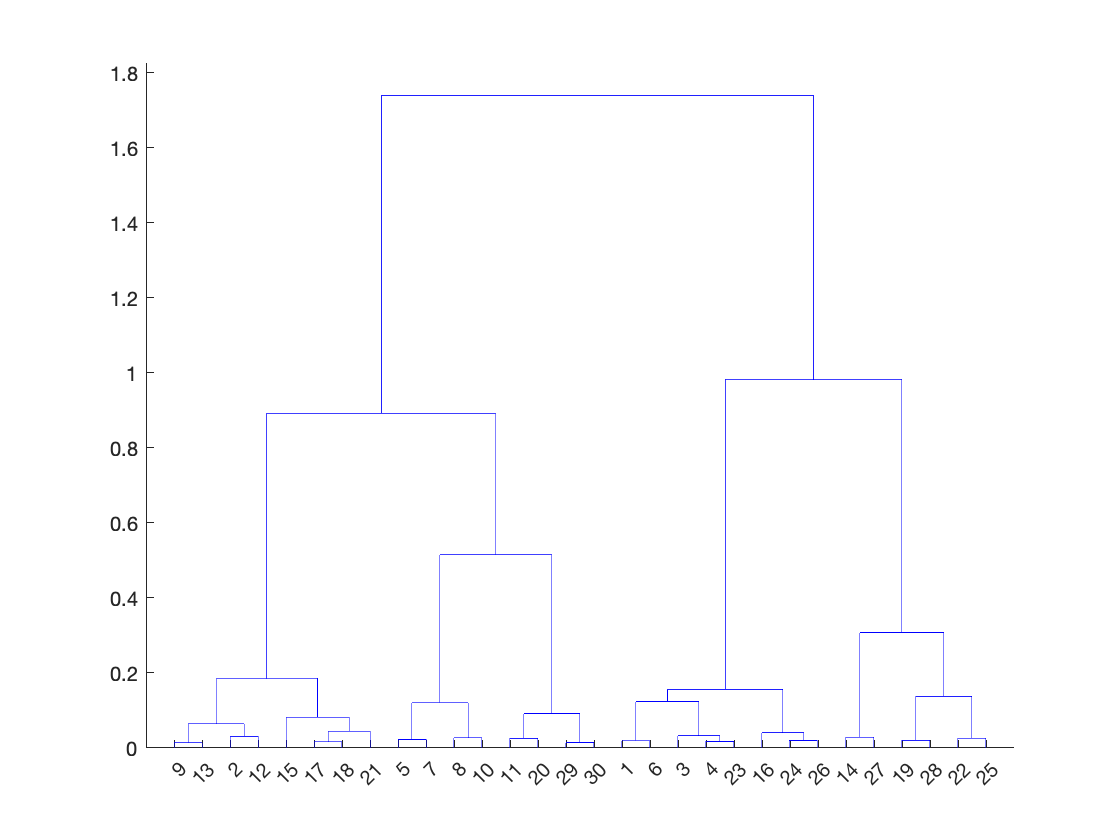





% (3) Hierarchical Clustering, the Cosine distance, and linkage "average
cosD = pdist(NewX,'cosine');
clustTreeCos = linkage(cosD,'average');
% visualizing the deandogram
 dendrogram(clustTreeCos)

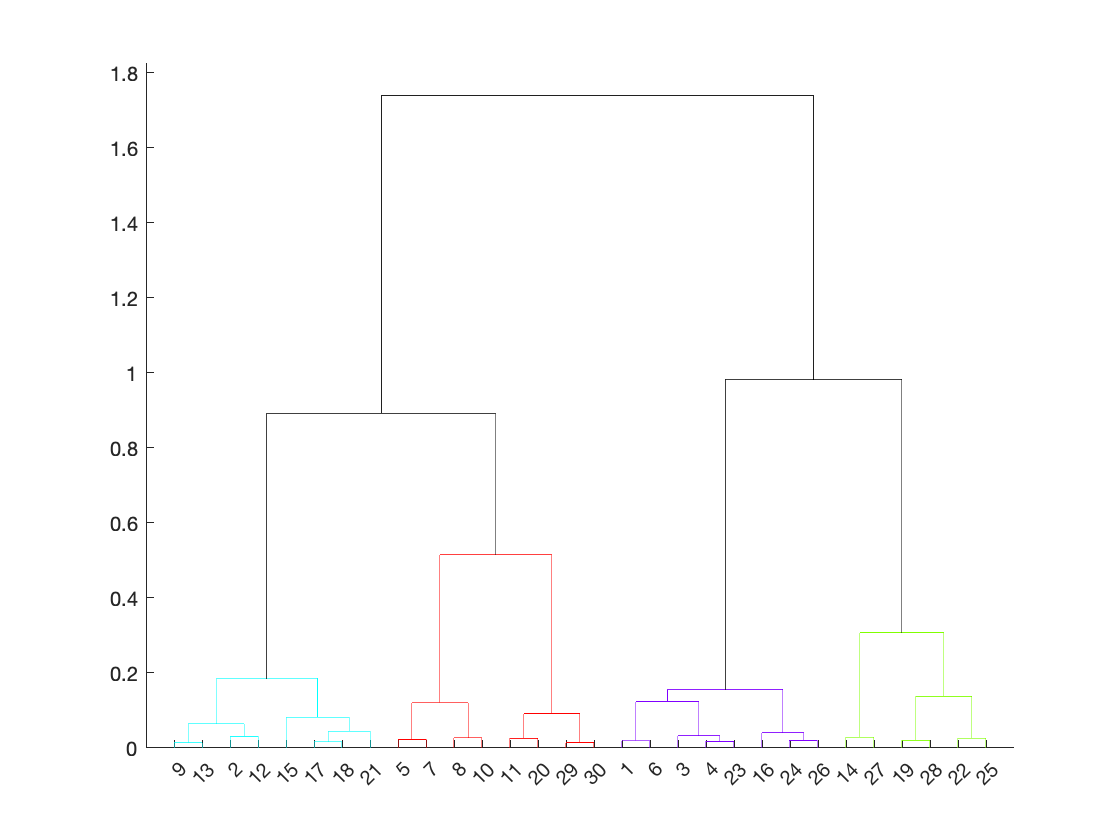

 hidxcos = cluster(clustTreeCos,'criterion','distance','cutoff',0.6);
 % observations  are alloted to four clusters and stored in variable
 % hidxcos to which cluster they belongs
 %Visualize the colored clusters in the dendrogram
 dendrogram(clustTreeCos,'ColorThreshold',0.6);

 % evaluating the cluster solution
f = @(NewX,k) clusterdata(NewX,'linkage','average','Distance','cosine','maxclust',k);
Eva = evalclusters(NewX,f,'silhouette','klist',[2:4])

Eva =   SilhouetteEvaluation with properties:

    NumObservations: 3202
         InspectedK: [2 3 4]
    CriterionValues: [0.6771 0.2968 0.3292]
           OptimalK: 2


%from the silhoutte value which is stored in variable Eva for cluster 2 it
% is visibled that it is highest as compared to cluster 3 and cluster 4 so
% we can evaluate cluster 2 is optimal cluster. cluster 4 is good as
% compared to 3 but not cluster 2 
 
 %(4) adopting gmm with k=3 
 rng("default")
 k = 3; % Number of GMM components
options = statset('MaxIter',1000); %iteration 1000
gm = fitgmdist(NewX,k,'Options',options);

% Probabilities are stored under variable P of each observation for in
P = posterior(gm,NewX)

P =     0.0002    0.9998    0.0000
    0.6163    0.0177    0.3660
    0.0000    1.0000    0.0000
    0.0000    1.0000         0
    0.9269    0.0731    0.0000
    0.1328    0.8672    0.0000
    0.9587    0.0413    0.0000
    0.3936    0.0120    0.5944
    0.1779    0.0068    0.8153
    0.1979    0.0082    0.7939


% Probability of a 8 th observation belonging to 1st cluster
P8C1=P(8,1);
% Probability of a 8 th observation belonging to 2st cluster
P8C2=P(8,2);
%Probability of a 8 th observation belonging to 3st cluster
P8C3=P(8,3);



## TASK 3


% (1)Dividing the datset for training and testing
Y2=table2array(Y2)

Y2 =    86.2500
   82.8750
   88.7500
   91.8333
   89.0000
   89.8750
   92.1250
   85.6250
   88.8750
   92.7500


cv = cvpartition(length(X),'holdout',0.30)

cv = Hold-out cross validation partition
   NumObservations: 3202
       NumTestSets: 1
         TrainSize: 2242
          TestSize: 960

Xtrain = X(training(cv),:)

Xtrain = 	1.0e+03 *

   -0.0129    0.7555    0.7559    0.0043   -0.0140   -0.0105    0.0194   -0.0147    0.0062    0.0093    0.0093    0.0011    0.0034    0.0003    0.1673    0.0078    2.0100    0.0010    0.0010
   -0.0174    0.7620    0.7624    0.0036   -0.0186   -0.0152    0.0279   -0.0196    0.0015    0.0011    0.0011    0.0006    0.0008    0.0000    0.0233    0.0011    2.0100    0.0010    0.0020
   -0.0095    0.7526    0.7530    0.0037   -0.0113   -0.0042    0.0341   -0.0110    0.0215    0.0119    0.0119    0.0014    0.0224    0.0211    0.0633    0.0307    2.0100    0.0010    0.0050
   -0.0112    0.7605    0.7609    0.0018   -0.0135   -0.0099    0.0175   -0.0125    0.0050    0.0025    0.0025    0.0008    0.0101    0.0010    0.1231    0.0050    2.0100    0.0010    0.0060
   -0.0086    0.7576    0.7580    0.0047   -0.0099   -0.0074    0.0070   -0.0097    0.0012    0.0042    0.0043    0.0008    0.0001    0.0001    0.0439    0.0015    2.0100    0.0010    0.0070
   -0.0154    0.7751    

Xtest = X(test(cv),:)

Xtest = 	1.0e+03 *

   -0.0126    0.7577    0.7581    0.0025   -0.0218   -0.0104    0.0193   -0.0141    0.0666    0.0171    0.0173    0.0017         0    0.1051    0.2369    0.0774    2.0100    0.0010    0.0030
   -0.0039    0.7506    0.7510    0.0034   -0.0077   -0.0024    0.0291   -0.0055    0.0035    0.0013    0.0013    0.0006    0.0004    0.0003    0.2723    0.0008    2.0100    0.0010    0.0040
   -0.0161    0.7651    0.7655    0.0040   -0.0170   -0.0120    0.0213   -0.0179    0.0047    0.0206    0.0209    0.0011    0.0072    0.0174    0.0199    0.0045    2.0100    0.0010    0.0080
   -0.0126    0.7773    0.7777    0.0018   -0.0156   -0.0124    0.0067   -0.0135    0.0040    0.0007    0.0007    0.0005    0.0042    0.0054    0.0163    0.0048    2.0100    0.0010    0.0100
   -0.0102    0.7724    0.7727    0.0027   -0.0138   -0.0083    0.0150   -0.0109    0.0093    0.0023    0.0023    0.0002    0.0004    0.0045    0.1054    0.0113    2.0100    0.0010    0.0110
   -0.0032    0.7679    0

Y2train = Y2(training(cv),:)

Y2train =    86.2500
   82.8750
   89.0000
   89.8750
   92.1250
   88.8750
   99.8571
   97.5000
   87.2500
   88.7500


Y2test = Y2(test(cv),:)

Y2test =    88.7500
   91.8333
   85.6250
   92.7500
   94.7500
   99.5000
   99.6250
   89.7500
   87.8750
   88.6250



% (2) Training a linear regression model
mdl1 = fitlm(Xtrain,Y2train,'linear');
%Linear regression model 1
mdl1

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)        139.23        25.059      5.5562     3.087e-08
    x1                 -4.313      0.069118     -62.401             0
    x2                 2.0843        1.3643      1.5277       0.12673
    x3                -2.1248        1.3637     -1.5582       0.11933
    x4                -0.2853      0.033173     -8.6006    1.4724e-17
    x5                0.29065      0.043747      6.6439    3.8298e-11
    x6         


% (3)Training the model by removing two variables
mdl2 = fitlm(Xtrain(:,3:19),Y2train,'linear');
%Linear regression model 2
mdl2

mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17

Estimated Coefficients:
                    Estimate         SE         tStat        pValue   
                   __________    __________    ________    ___________

    (Intercept)        252.76        41.446      6.0986     1.2578e-09
    x1              -0.084218     0.0068127     -12.362     5.3473e-34
    x2                -0.5769      0.054462     -10.593     1.2986e-25
    x3                -1.5686      0.053103     -29.539    4.6046e-162
    x4                -2.2199      0.047539     -46.697              0
    x5                -0.1123     0.0058498     -19.197     4.0574e-76
    x6          


% Applying model 1 over test data
YTest_predicted = predict(mdl1,Xtest);
% Applying model 2 over test data
YTest_predicted2 = predict(mdl2,Xtest(:,3:19));

%(4)
% mean squarred error for 1st model
MSE1= immse(Y2test,YTest_predicted)

MSE1 = 1.9000


% mean squarred error for 2nd model
MSE2= immse(Y2test,YTest_predicted2)

MSE2 = 5.3171

% The MSE for models 1 and 2 (after removing the variable) is 1.900 and 5.3171 respectively. In comparison to model 2, MSE for model 1 is low. On the basis of MSE, we may conclude that model 1 is better performing than model 2.

%(5)
rng("default")
[coeff1,scoreTrain1,~,~,explained1,mu1] = pca(Xtrain);

%model using the first 2 principal components
scoreTrain2 = scoreTrain1(:,1:2)

scoreTrain2 =    89.8476  -37.7108
  -54.2402  -45.6092
  -13.7773  -26.6889
   45.3106  -34.7084
  -33.8415  -32.2964
  -63.4817  -45.5105
  -54.1518  -22.9530
  -16.9075  -23.1325
  194.2079  -20.7626
   56.8926  -27.7612


PCA_mdl1=fitlm(scoreTrain2,Y2train)

PCA_mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)        80.6      0.23803     338.62             0
    x1             0.025149    0.0025279     9.9487    7.5536e-23
    x2             -0.17984     0.013383    -13.438    1.1917e-39


Number of observations: 2242, Error degrees of freedom: 2239
Root Mean Squared Error: 11.3
R-squared: 0.111,  Adjusted R-Squared: 0.11
F-statistic vs. constant model: 140, p-value = 6.25e-58


%model using the first 3 principal components
scoreTrain3 = scoreTrain1(:,1:3)

scoreTrain3 =    89.8476  -37.7108   -5.9295
  -54.2402  -45.6092    4.4473
  -13.7773  -26.6889   -1.0031
   45.3106  -34.7084    2.2199
  -33.8415  -32.2964   -9.7397
  -63.4817  -45.5105   16.0669
  -54.1518  -22.9530    3.4953
  -16.9075  -23.1325   12.8371
  194.2079  -20.7626   31.0380
   56.8926  -27.7612   25.2445


PCA_mdl2=fitlm(scoreTrain3,Y2train)

PCA_mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)        80.6      0.21198     380.22             0
    x1             0.025149    0.0022513     11.171    3.1053e-28
    x2             -0.17984     0.011919    -15.089    4.5464e-49
    x3             -0.39993     0.016535    -24.187    5.175e-115


Number of observations: 2242, Error degrees of freedom: 2238
Root Mean Squared Error: 10
R-squared: 0.295,  Adjusted R-Squared: 0.294
F-statistic vs. constant model: 312, p-value = 1.9e-169

%model using the first 4 principal components
scoreTrain4 = scoreTrain1(:,1:4)

scoreTrain4 =    89.8476  -37.7108   -5.9295    2.5633
  -54.2402  -45.6092    4.4473    6.8867
  -13.7773  -26.6889   -1.0031   26.2594
   45.3106  -34.7084    2.2199   -3.5295
  -33.8415  -32.2964   -9.7397  -10.4121
  -63.4817  -45.5105   16.0669   -3.2240
  -54.1518  -22.9530    3.4953  -15.3511
  -16.9075  -23.1325   12.8371   -3.0358
  194.2079  -20.7626   31.0380  -10.4888
   56.8926  -27.7612   25.2445   -4.8476


PCA_mdl3=fitlm(scoreTrain4,Y2train)

PCA_mdl3 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)        80.6       0.1733     465.09              0
    x1             0.025149    0.0018405     13.665     6.9083e-41
    x2             -0.17984    0.0097439    -18.457     6.4484e-71
    x3             -0.39993     0.013518    -29.586    1.2322e-162
    x4             -0.52991     0.015894     -33.34    3.2818e-198


Number of observations: 2242, Error degrees of freedom: 2237
Root Mean Squared Error: 8.21
R-squared: 0.529,  Adjusted R-Squared: 0.528
F-statistic vs. constant model: 629, p-value = 0



%Test data for PCA model 1

scoreTest2 = (Xtest-mu1)*coeff1(:,1:2);

%Test data for PCA model 2

scoreTest3 = (Xtest-mu1)*coeff1(:,1:3);

%Test data for PCA model 3

scoreTest4 = (Xtest-mu1)*coeff1(:,1:4);

%prediction for target variable by model 1
PCA_YTest_predicted1= predict(PCA_mdl1,scoreTest2)

PCA_YTest_predicted1 =    92.1715
   88.7041
   87.4826
   86.7519
   87.7251
   82.8322
   87.0671
   86.9530
   88.4913
   87.1659


%prediction for target variable by model 2
PCA_YTest_predicted2= predict(PCA_mdl2,scoreTest3)

PCA_YTest_predicted2 =    86.1769
   90.1777
   87.4652
   80.0607
   81.5646
   81.3136
   82.7820
   75.6542
   77.5287
   75.7113


%prediction for target variable by model 3
PCA_YTest_predicted3= predict(PCA_mdl3,scoreTest4)

PCA_YTest_predicted3 =    73.8674
   89.3080
   80.1899
   88.7505
   86.4910
   88.5438
   90.7259
   77.6508
   79.8247
   76.8009





% mean squarred error for 1st model
MSE_pcr1 = immse(Y2test,PCA_YTest_predicted1)

MSE_pcr1 = 126.2265


% mean squarred error for 2nd model
MSE_pcr2 = immse(Y2test,PCA_YTest_predicted2)

MSE_pcr2 = 97.8002


% mean squarred error for 3rd model
MSE_pcr3 = immse(Y2test,PCA_YTest_predicted3)

MSE_pcr3 = 65.6037

%After getting MSE for 3 model we cocluded that model with 4 principal
%componenet is best .As it has a lower mse value of 68 .


TASK 4


%(1) Holdout partition with the same ration of 70:30 for training and
%testing  Now we will use variable Y1 
rng('default')  %for reproductivity
Y1=table2array(Y1)

Y1 =      1
     1
     0
     0
     0
     0
     0
     1
     1
     1


cv = cvpartition(length(X),'holdout',0.30)

cv = Hold-out cross validation partition
   NumObservations: 3202
       NumTestSets: 1
         TrainSize: 2242
          TestSize: 960

Xtrain = X(training(cv),:)

Xtrain = 	1.0e+03 *

   -0.0129    0.7555    0.7559    0.0043   -0.0140   -0.0105    0.0194   -0.0147    0.0062    0.0093    0.0093    0.0011    0.0034    0.0003    0.1673    0.0078    2.0100    0.0010    0.0010
   -0.0174    0.7620    0.7624    0.0036   -0.0186   -0.0152    0.0279   -0.0196    0.0015    0.0011    0.0011    0.0006    0.0008    0.0000    0.0233    0.0011    2.0100    0.0010    0.0020
   -0.0095    0.7526    0.7530    0.0037   -0.0113   -0.0042    0.0341   -0.0110    0.0215    0.0119    0.0119    0.0014    0.0224    0.0211    0.0633    0.0307    2.0100    0.0010    0.0050
   -0.0112    0.7605    0.7609    0.0018   -0.0135   -0.0099    0.0175   -0.0125    0.0050    0.0025    0.0025    0.0008    0.0101    0.0010    0.1231    0.0050    2.0100    0.0010    0.0060
   -0.0086    0.7576    0.7580    0.0047   -0.0099   -0.0074    0.0070   -0.0097    0.0012    0.0042    0.0043    0.0008    0.0001    0.0001    0.0439    0.0015    2.0100    0.0010    0.0070
   -0.0154    0.7751    

Xtest = X(test(cv),:)

Xtest = 	1.0e+03 *

   -0.0126    0.7577    0.7581    0.0025   -0.0218   -0.0104    0.0193   -0.0141    0.0666    0.0171    0.0173    0.0017         0    0.1051    0.2369    0.0774    2.0100    0.0010    0.0030
   -0.0039    0.7506    0.7510    0.0034   -0.0077   -0.0024    0.0291   -0.0055    0.0035    0.0013    0.0013    0.0006    0.0004    0.0003    0.2723    0.0008    2.0100    0.0010    0.0040
   -0.0161    0.7651    0.7655    0.0040   -0.0170   -0.0120    0.0213   -0.0179    0.0047    0.0206    0.0209    0.0011    0.0072    0.0174    0.0199    0.0045    2.0100    0.0010    0.0080
   -0.0126    0.7773    0.7777    0.0018   -0.0156   -0.0124    0.0067   -0.0135    0.0040    0.0007    0.0007    0.0005    0.0042    0.0054    0.0163    0.0048    2.0100    0.0010    0.0100
   -0.0102    0.7724    0.7727    0.0027   -0.0138   -0.0083    0.0150   -0.0109    0.0093    0.0023    0.0023    0.0002    0.0004    0.0045    0.1054    0.0113    2.0100    0.0010    0.0110
   -0.0032    0.7679    0

Y1train = Y1(training(cv),:)

Y1train =      1
     1
     0
     0
     0
     1
     0
     1
     1
     1


Y1test = Y1(test(cv),:)

Y1test =      0
     0
     1
     1
     1
     1
     1
     1
     1
     1



% (2) training a logistic regression model
aglm = fitglm(Xtrain,Y1train,'Distribution','binomial','Link','logit')

aglm = Generalized linear regression model:
    logit(y) ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19
    Distribution = Binomial

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)       -240.44        48.163     -4.9923    5.9676e-07
    x1                0.24141       0.13173      1.8326      0.066858
    x2                -4.2362        2.5263     -1.6769      0.093565
    x3                 4.3313        2.5253      1.7151      0.086322
    x4               -0.25491       0.06256     -4.0747     4.607e-05
    x5                0.36909      0.086367      4.2

% We apply glm model over test data stored the probabilities in Y_glm
Y_glm = predict(aglm, Xtest)

Y_glm =     0.2707
    0.2296
    0.8383
    0.9009
    0.6778
    0.7005
    0.6019
    0.9268
    0.9362
    0.9516




% (3) PCA over train data
[coeff4,scoretrain9,~,~,explained4,mu4] = pca(Xtrain);
% using first three component  for training classification model
scoretrain7=scoretrain9(:,1:3)

scoretrain7 =    88.9979  -37.7993   -6.4849
  -55.0784  -45.6878    4.2818
  -14.6286  -26.9543   -1.7066
   44.4879  -34.8189    1.7208
  -34.6830  -32.1265   -9.9379
  -64.2998  -45.5883   15.7174
  -54.9587  -22.8504    3.4139
  -17.7147  -23.1712   12.6322
  193.4445  -21.1956   30.5471
   56.1068  -28.0442   24.9342


% training a classification tree model
tglmg = fitctree(scoretrain7,Y1train)

tglmg =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 2242


  Properties, Methods


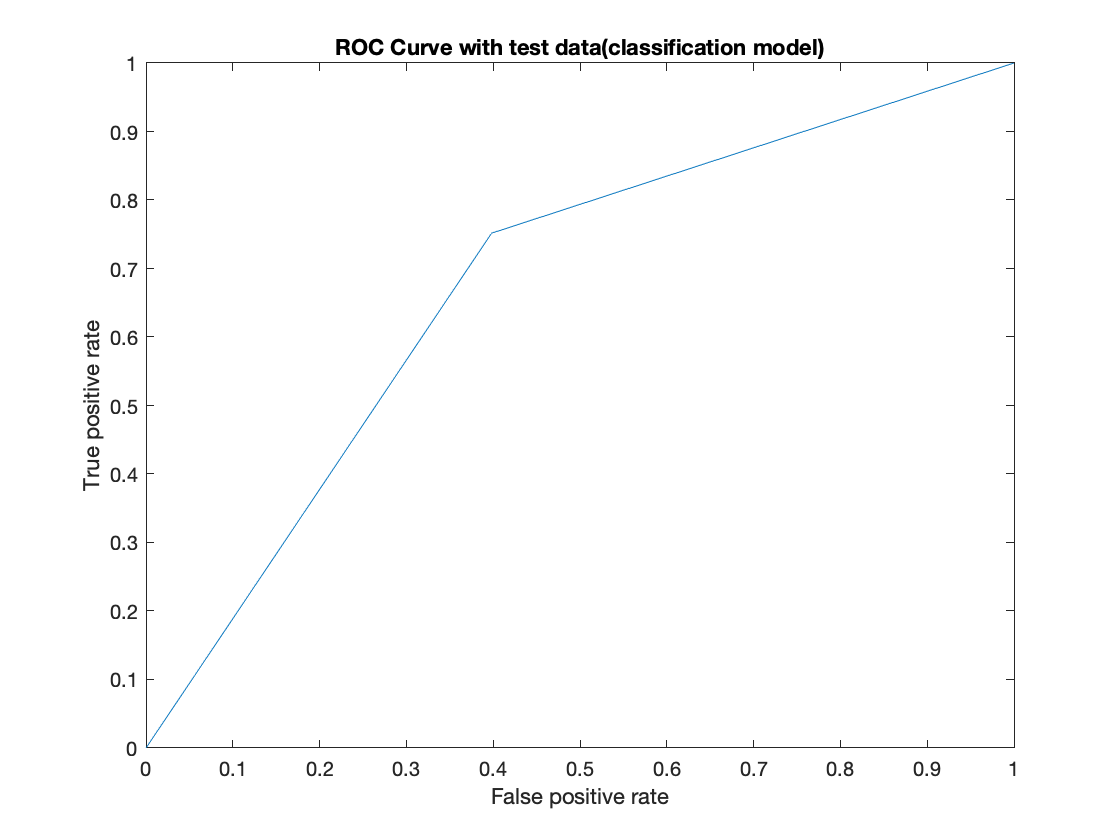

Xtestk = (Xtest-mu4)*coeff4(:,1:3);

% Predicting values of Y1  using classification model and storing its value
% in Y_thhh
Y_thhh = predict(tglmg,Xtestk);

%(4) ROC curve with test data(classification model)
[xxtest,yytest,Tresholds,auctest] = perfcurve(Y1test,Y_thhh,'1');
figure;
plot(xxtest,yytest)
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with test data(classification model)')

%AUC for classification model
auctest

auctest = 0.6767

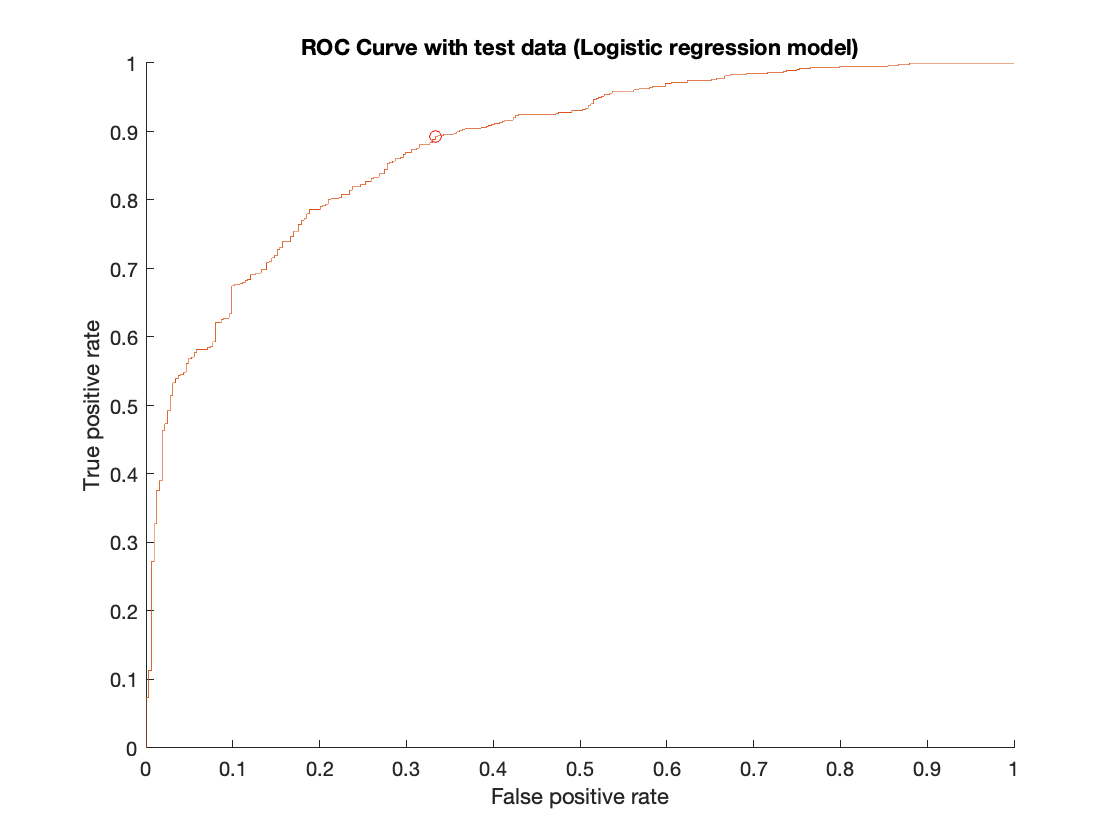





% ROC curve with test data (Logistic regression)
[xxtest2,yytest2,Tresholds2,auctest2,OPTROCPT ] = perfcurve(Y1test,Y_glm,'1');
figure;
hold on
plot(OPTROCPT(1),OPTROCPT(2),'ro')
plot(xxtest2,yytest2)
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with test data (Logistic regression model)')
hold off

% AUC test for logistic regression model
auctest2

auctest2 = 0.8799

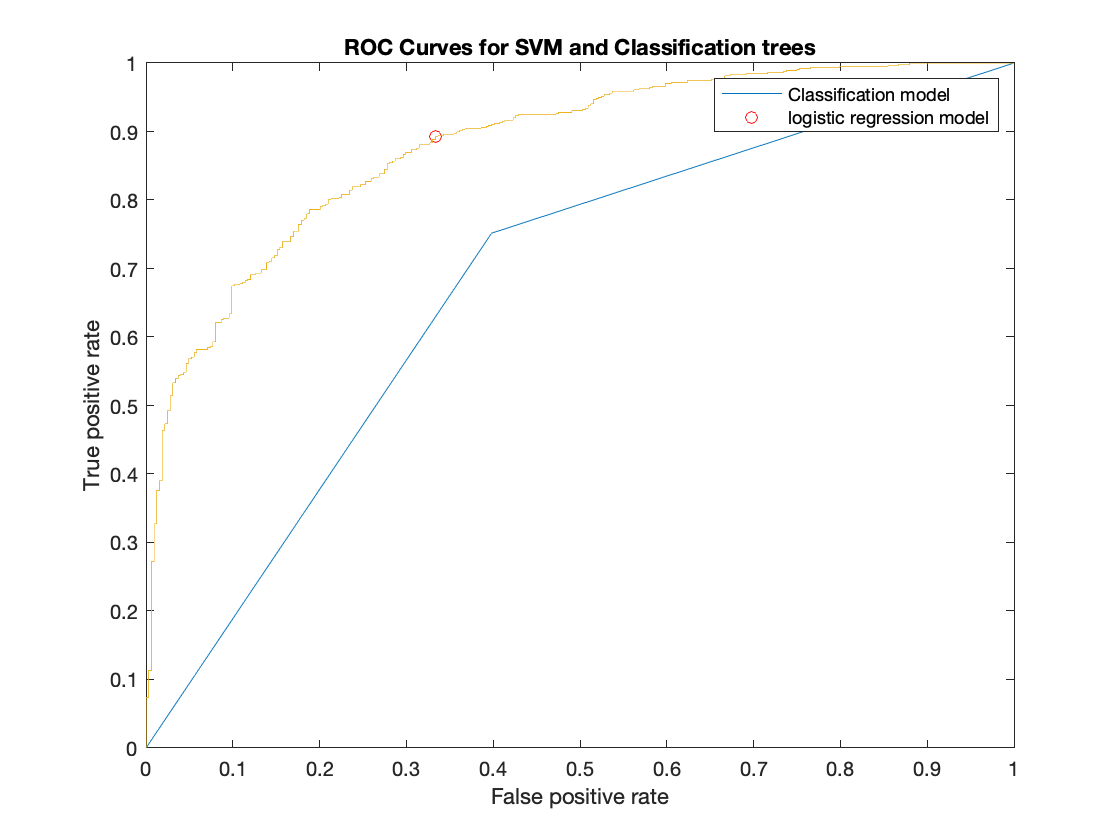


% (5) visualizin both ROC curve together
figure
plot(xxtest,yytest)
hold on
plot(OPTROCPT(1),OPTROCPT(2),'ro')
plot(xxtest2,yytest2)
legend('Classification model' , 'logistic regression model')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for SVM and Classification trees')
hold off

## **TASK 5**

rng('default') % For reproducibility

%(1)
%creating a random partition 4-fold cross-validation.
cvp = cvpartition(Y1train,'KFold',4);
% training a svm model with kernal function gaussian and kernelscale auto
mdlRSVM1 = fitcsvm(Xtrain,Y1train,'Standardize',true,'KernelFunction','gaussian','KernelScale','auto','CVPartition',cvp);

%Error rate in svm model
error_svm2 = kfoldLoss(mdlRSVM1)

error_svm2 = 0.2212

%accuracy of svm model
accuracy_svm2 = 1 - error_svm2

accuracy_svm2 = 0.7788




% training  a classification tree model, (setting the minimum number of samples required at a
% leaf node at 15)
t2=fitctree(Xtrain,Y1train,'MinLeafSize',15);
CVRt2=crossval(t2,'KFold',4);
%Error rate in classification tree model 
error_t2 = kfoldLoss(CVRt2)

error_t2 = 0.2489

%Accuracy in classification tree model
Accuracy_t2 = 1-error_t2

Accuracy_t2 = 0.7511






%training  classification tree model, (setting the maximum number of splits at 5)
t3=fitctree(Xtrain,Y1train,'MaxNumSplits',5);
CVRt3=crossval(t3,'kfold',4)

CVRt3 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'}
           ResponseName: 'Y'
        NumObservations: 2242
                  KFold: 4
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


%Error in classification tree model 
error_t3=kfoldLoss(CVRt3)

error_t3 = 0.2676

% accuracy in classification model 
Accuracy_t3 = 1-error_t3

Accuracy_t3 = 0.7324


%(2)
% If we check with the accuracy svm model with  gaussian KernelFunction and
%auto as KernelScale is best as compared to other two classification tree.


%AUC for SVM model
scorekSVMModel = fitSVMPosterior(mdlRSVM1);
[predictionsvm, Posterior_svm] = kfoldPredict(scorekSVMModel)

predictionsvm =      0
     1
     1
     1
     0
     1
     0
     1
     1
     1


Posterior_svm =     0.5671    0.4329
    0.2256    0.7744
    0.3563    0.6437
    0.1965    0.8035
    0.7672    0.2328
    0.2055    0.7945
    0.6007    0.3993
    0.2842    0.7158
    0.2149    0.7851
    0.1080    0.8920


[X1svm,Y1svm,~,AUC1svm] = perfcurve(Y1train,Posterior_svm(:,2),'1');
% AUC for svm model
AUC1svm

AUC1svm = 0.8407



%AUC for classification tree  (setting the minimum number of samples required at a
% leaf node at 15)
[predictionstree, Posterior_t] = kfoldPredict(CVRt2)

predictionstree =      0
     1
     1
     1
     0
     1
     1
     1
     1
     1


Posterior_t =     0.6470    0.3530
    0.0512    0.9488
    0.1113    0.8887
    0.2000    0.8000
    1.0000         0
    0.0387    0.9613
    0.0780    0.9220
    0.2500    0.7500
    0.1581    0.8419
    0.0476    0.9524


[Xt11,Yt11,~,AUCt22] = perfcurve(Y1train,Posterior_t(:,2),'1');
%AUC 
AUCt22

AUCt22 = 0.8086




% AUC tree for classification tree model, (setting the maximum number of splits at 5)
[predictionstree11, Posterior_t2] = kfoldPredict(CVRt3)

predictionstree11 =      0
     1
     1
     1
     0
     1
     1
     1
     1
     1


Posterior_t2 =     0.7300    0.2700
    0.1271    0.8729
    0.1378    0.8622
    0.3777    0.6223
    0.5678    0.4322
    0.1861    0.8139
    0.2528    0.7472
    0.1171    0.8829
    0.1861    0.8139
    0.1171    0.8829


[Xt32,Yt32,~,AUCt24] = perfcurve(Y1train,Posterior_t2(:,2),'1');

AUCt24

AUCt24 = 0.7451



% Even with the AUC test we find out that the best model is svm 
% WE use all the data in final model

%OUR FInal model will be
Final_model= fitcsvm(Xtrain,Y1train,'Standardize',true,'KernelFunction','gaussian','KernelScale','auto');

% Predicting the output Y1 using final modeln 
% WE WILL USE THE TEST DATA FOR PERFORMANCE OF MODEL USING CONFUSION CHART
predicted_classes_t65 = predict(Final_model,Xtest)

predicted_classes_t65 =      1
     0
     1
     1
     1
     0
     0
     1
     1
     1


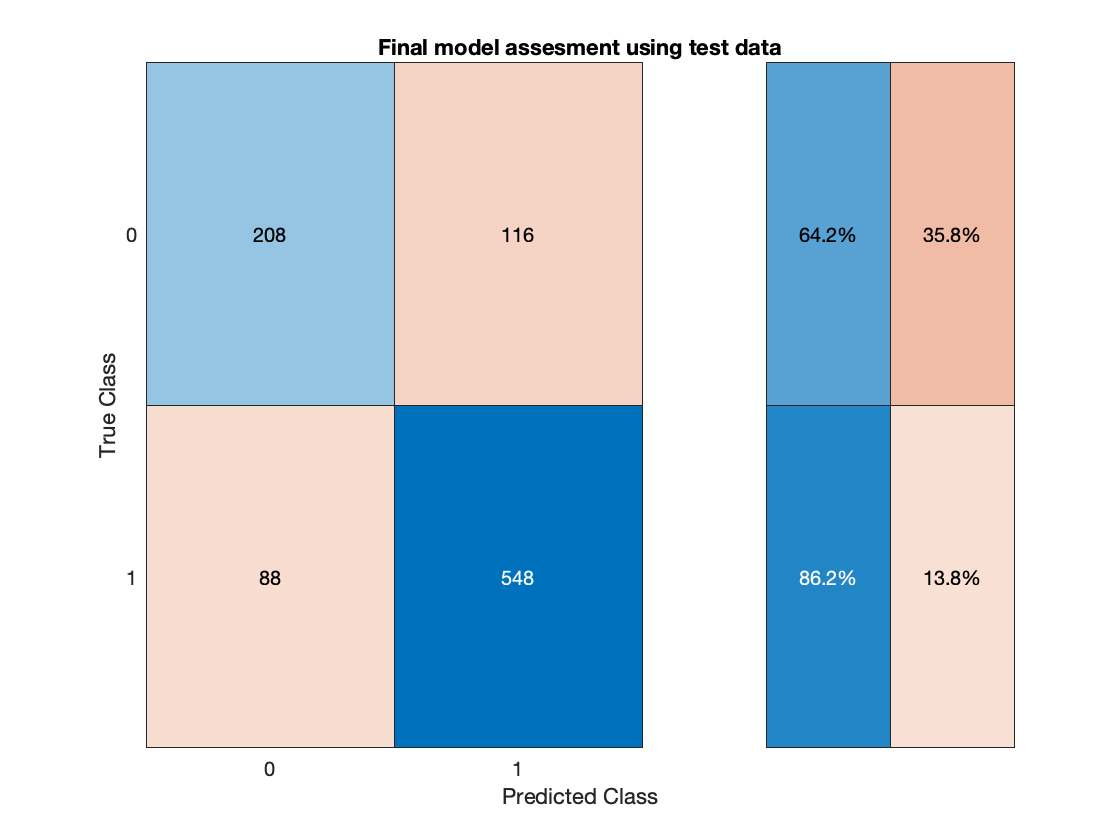



%(3)
% testing performace of choosen model using confusion chart
figure;
c98=confusionchart(Y1test,predicted_classes_t65,'RowSummary','row-normalized');
title("Final model assesment using test data")


% Accuracy of final model using test
accuracy_final_model=(208+548)/960

accuracy_final_model = 0.7875



%(4) model and data used is explained in report










